# 最小二乗法の計算例

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;

乱数を初期化する．かっこの中の数値を変えると異なる乱数が生成される．

%rng(2) %コメントを外すと書籍を同じ図が得られます

y=axの場合

N=30;   %データの計測回数
a=2;    %真の値
x=randn(N,1);
y=a*x+randn(N,1);   %真の値a*xに乱数を加えている
figure
scatter(x,y);
set(gca,'fontname','メイリオ','fontsize',14);grid on;

最小二乗法の推定値

aHat=inv(x'*x)*x'*y

aHat = 2.3686

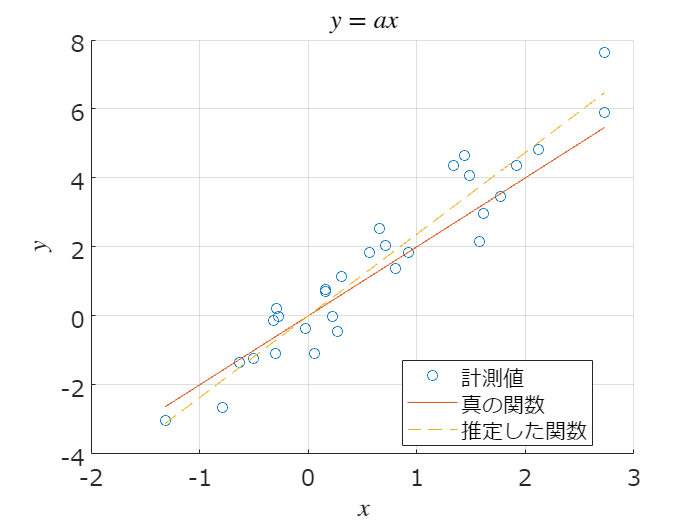

hold on;
plot([min(x) max(x)],a*[min(x) max(x)],'-');
plot([min(x) max(x)],aHat*[min(x) max(x)],'--');
legend({'計測値','真の関数','推定した関数'},'Location','best')
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
title('$y=ax$','Interpreter','latex')
exportgraphics(gcf,'fig_LMSExample01.pdf')

y=ax+bの場合

N=30;a=2;b=-1;
x=randn(N,1);
y=a*x+b+randn(N,1);
xMat=[x ones(size(x))];

係数の推定値

aHat=inv(xMat'*xMat)*xMat'*y

aHat =     1.7847
   -1.0249


疑似逆行列を使ってみる

pinv(xMat)*y

ans =     1.7847
   -1.0249


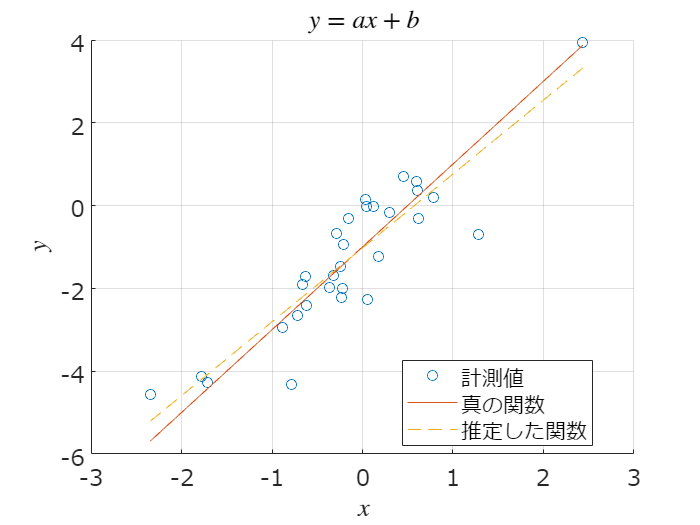

figure
scatter(x,y);
set(gca,'fontname','メイリオ','fontsize',14);grid on;
hold on;
plot([min(x) max(x)],a*[min(x) max(x)]+b,'-');
plot([min(x) max(x)],aHat(1)*[min(x) max(x)]+aHat(2),'--');
legend({'計測値','真の関数','推定した関数'},'Location','best')
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
title('$y=ax+b$','Interpreter','latex')
exportgraphics(gcf,'fig_LMSExample02.pdf')